We refer back to our previous work: [Geometric Mechanics of Nonslip Contact in a Planar Quadruped](https://arxiv.org/abs/2308.14357), where using a single level-set around the origin of the continuous shape subspace decoupled through shared stance, we tuned subgaits to achieve complicated average locomotion control and steering through a two-beat trot gait.

Here, using the mobility framework and discrete CCFs/stratified panels, we want to show that gait controllability is guaranteed.

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
end
load(dataName); load(dataMotPlanName);

siIdx = 5; % choose legs 1 and 3 for the first contact state 
% this happens to FR and HL legs in stance during a trot gait
% this stance phase belongs to which two-beat gait?
% ... we know this is trot, but here's a programmatic way to obtain the
% ... same, helps automate most of the gait design process
[siRow, siCol] = find(kin.cs_IdxFor2bGaits == siIdx);
sjRow = siRow; % the row remains the same

% switch the column for the other stance phase
% ... we ensure that the ordering is as specified in the 
switch siCol, case 1, sjCol = 2; case 2, siCol = 1; sjCol = 2; end

% stance phases i and j and the corresponding legs are given below
cs_i = kin.cs( kin.cs_IdxFor2bGaits(siRow, siCol), : )

cs_i =      1     3


cs_j = kin.cs( kin.cs_IdxFor2bGaits(sjRow, sjCol), : )

cs_j =      2     4


The way this is setup so that you can choose the submanifolds in any order and the result doesn't switch the ordering.

Let's choose the first submanifold in a trot gait first.

sIdx = kin.cs_IdxFor2bGaits(siRow, siCol);

Exploring the continuous shape subspace of stancing limbs in the current level-2 submanifold.

% unpack the limb length ratio `a' and body length parameter `l'
% ... given `l', the limb length is defined as `a' in the range of (0, 1]
% ... `l' is the x and y offset needed to reach any hip joint frame ($h_ib$)
% ... from the body centroid/COM, ($h_b$)
a = kinfunc{sIdx}.aa;
l = kinfunc{sIdx}.aa;

% get the integration limits
alpha_limits = [p_info{sIdx}.xlimits;
                p_info{sIdx}.ylimits] 

alpha_limits =    -1.5708    1.5708
   -1.5708    1.5708


% this is a constant limit, doesn't change between limbs

% the continuous shape subspace
% ... continuous because we aren't considering discrete contact shape,
% ... \beta at the moment
% ... this will help us extract the zero contour of the \theta-panel 
ai = p_kin{sIdx}.ai; aj = p_kin{sIdx}.aj;

% Salient points .................................................. %
% explore the entire limb angle range to find the singularities
% ... these singularities occur at extremal values of F
% ... take the ranges of both limb angles to be +-pi
% ... we shall use `fmincon' to identify these points
% ... also, since we need the function to compute F, we shall store that
% ... instead of calling it from struct every single time (give
% ... brain-damage bruh, trust me!)
% ................................................................. %

% for our initial analysis, we shall consider the origin as a constant
% reference point
refPtOrg = zeros(1, 2);

% unpack the functions needed
% ... squared, inter-leg distance for the stancing feet
F_fxnNow = kin.ksq_ij{sIdx};

% the contracting singularity when the stancing legs are closest to each
% other
% ... we minimize F for this directly
aInf = fmincon(@(x) F_fxnNow(a, l, x(1), x(2)), ... % set fixed a and l, and iterate over x
                refPtOrg, [], [], [], [], ... % ic for limb angles at the origin
                -pi*ones(1, 2), pi*ones(1, 2)); % bounds for the unlocked limb angles


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% ... corresponding F value
F_inf = F_fxnNow(a, l, aInf(1), aInf(2))

F_inf = 0.6863


% the expanding singularity when the stancing legs are the farthest away
% from each other
% ... we maximize F indirectly by minimizing -F
aSup = fmincon(@(x) -F_fxnNow(a, l, x(1), x(2)), ...
                refPtOrg, [], [], [], [], ... 
                -pi*ones(1, 2), pi*ones(1, 2));


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


F_sup = F_fxnNow(a, l, aSup(1), aSup(2))

F_sup = 23.3137

% Remove all F-levels that are within a certain neighborhood of the
% singularities by setting percentage bounds on the F-levels
% ... let's try different ranges and see what works best for us
F_range  = F_sup - F_inf;
prctRm = 10; % SET PERCENTAGE FOR BOUNDS HERE
F_bounds = prctRm/100*F_range*[+1 -1] + [F_inf F_sup]; % pull the bounds inwards

Generate a function that checks if the limb angle solution are within desired `F_bounds' and angle bounds as those are the only solutions we can use.

function [value, isTerminal, direction] = shapeBoundsEvent(~, y, F_fxn, shapeArgs)

    % `direction' output doesn't matter
    % ... this is if a event happens either increasingly or decreasingly
    % ... computed from `value' var
    % ... we just set direction to 0
    direction = 0;

    % unpack
    aLimits = shapeArgs.aLimits;
    % 1) check if the shape values are within the predefined shape 
    % space bounds
    aLimCheck = (y(1) >= aLimits(1, 1) && y(1) <= aLimits(1, 2) ...
                && y(2) >= aLimits(2, 1) && y(2) <= aLimits(2, 2));
    % if the check didn't "check out" LOL, then return event
    if ~aLimCheck
        value = 0; isTerminal = 1; return 
    end

    % 2) continue unpacking if the limits are okay
    a = shapeArgs.a;
    l = shapeArgs.l;
    F_bounds = shapeArgs.F_bounds;
    % compute the F-value
    F_now = F_fxn(a, l, y(1), y(2));
    % check if the bounds are satisfied
    F_check = ( F_now >= F_bounds(1) && F_now <= F_bounds(2) );
    % check if the shape
    if ~F_check
        value = 0; isTerminal = 1; direction = 0; return
    end

    % if you're here, the all checks "checked out" LOL, so return simply
    value = 1; isTerminal = 0;

end

Now, we need to obtain the path along the gradient of $F$ passing through the origin and doesn't hit the bounds for level-sets we computed earlier. The easiest way I can think of doing this is to setup ode45 along the gradient directions with a stopping event when the bounds are violated.

Another stopping event needs requires a minimum forward and backward integration length of $1.2$ about the refernce point. This also needs to be baked in into the formulation below. Note that this would be an integration at each point along level-sets of $F$. 

% get the function to compute gradients
gradF_dirn_now = kin.dksq_dirn_ij{sIdx};

% intialize a structure to hold all the solutions
gradFIntegralCurve = []; % parent structure to hold all the integral curve information
gradFIntegralCurve.odeOptions = []; % initialize the integration options
gradFIntegralCurve.fwd_soln = []; gradFIntegralCurve.bwd_soln = [];

% setup the auxiliary arguments needed for the events function
shapeArgs.a = a; shapeArgs.l = l; shapeArgs.aLimits = alpha_limits; shapeArgs.F_bounds = F_bounds;

% setup the options for integration
gradFIntegralCurve.odeOptions = odeset('Events', @(t, y) shapeBoundsEvent(t, y, F_fxnNow, shapeArgs));

Now that we have the event function setup and a way to stop once we connect forward and backward on closed level-sets that are within allowable $F$-bounds, we now just need to integrate forward and backward from the origin.

[tNow, yNow, teNow, yeNow, ieNow] = ...
    ode45( @(t, y) +gradF_dirn_now(a, l, y(1), y(2)), ... % run the states into the gradient direction as the velocity
            [0 25], ... % time-span, it should be large enough to reach the F or shape space bounds (play around with it!)
            refPtOrg, ... % we are always going to start at the origin, unless its outside the Fbounds.
            gradFIntegralCurve.odeOptions ); % pass the bound violation events we setup earlier
gradFIntegralCurve.fwd_soln.t  = tNow;
gradFIntegralCurve.fwd_soln.y  = yNow;
gradFIntegralCurve.fwd_soln.te = teNow;
gradFIntegralCurve.fwd_soln.ye = yeNow;
gradFIntegralCurve.fwd_soln.ie = ieNow;

We stopping in like 0.2 shape space length units (obviously under a unity metric), which is quite quick and implies that the origin was already pretty close to the $F$-bounds we computed earlier.

The backward solution:

[tNow, yNow, teNow, yeNow, ieNow] = ...
    ode45( @(t, y) -gradF_dirn_now(a, l, y(1), y(2)), ... % negate the gradient direction to integrate backwards
            [0 25], ... 
            refPtOrg, ... 
            gradFIntegralCurve.odeOptions );
gradFIntegralCurve.bwd_soln.t  = tNow;
gradFIntegralCurve.bwd_soln.y  = yNow;
gradFIntegralCurve.bwd_soln.te = teNow;
gradFIntegralCurve.bwd_soln.ye = yeNow;
gradFIntegralCurve.bwd_soln.ie = ieNow;

Now, we obtain the range of different F-levels by starting at the event location of the backward solution and integrating all the way forward with sum of the forward and backward event times.

gradFIntegralCurve.main_soln = [];                        % initialize the solution struct
yeFwd = gradFIntegralCurve.fwd_soln.ye;                   % the fwd event as the initial condition 
                                                          % ... and integrating backward until the event is reached
tEnd = gradFIntegralCurve.bwd_soln.te...
    + gradFIntegralCurve.fwd_soln.te;                     % integrate for the total event duration to get to the other end
[tNow, yNow, teNow, yeNow, ieNow] = ...
    ode45( @(t, y) -gradF_dirn_now(a, l, y(1), y(2)), ... % negate the gradient direction to integrate backwards from forward event
            linspace(0, tEnd, size(ai, 1)), ...           % use the discretization of the continuous shape space from earlier
            yeFwd, ... 
            gradFIntegralCurve.odeOptions );
gradFIntegralCurve.main_soln.t  = tNow;                   % store this solution for later use
gradFIntegralCurve.main_soln.y  = yNow;
gradFIntegralCurve.main_soln.te = teNow;
gradFIntegralCurve.main_soln.ye = yeNow;
gradFIntegralCurve.main_soln.ie = ieNow;

With this main solution, we have obtained the slipping coordinate of the nonslip-slip coordinate system and as this coordinate is perpendicular to our nonslip level-sets over which the stance phase paths are described, we shall denote it as ${\Delta \alpha}^{\perp}_{i}$. Correspondingly, the nonslip directions will be ${\Delta \alpha}^{\parallel}_{i}$. In both symbols, `$i$' denotes the current stance phase or subgait index.

Next, we need to identify the shape space paths at different level-sets of $F$. In the aforementioned previous work, we used forward and backward integration length of 1.2 and we shall further restrict the level-sets based on this availability along the $\Delta F$ integral curve (satisfying pre-determined bounds).

% get the function to integrate along the level-sets of F
gradF_perpDirn_now = kin.dpsi_ij_s_vector{sIdx};

% integrate and obtain the two endpoints to define the accessible level-set
% ... 1) integrate backward and obtain the ic from reference to integrate
% ... forward
integration_time = 1.2*ones(1, 2); % [backward, forward] integration lengths
[~, tempY] = ode45( @(t,y) -gradF_perpDirn_now(a, l, y(1), y(2)), ...
    [0, integration_time(1)], refPtOrg ); 
% ... 2) integrate forward to the presribed end based on integration length
[nonslipIC_time, nonslipIC_values] = ode45( @(t,y) -gradF_perpDirn_now(a, l, y(1), y(2)), ...
    linspace(0, sum(integration_time), size(ai, 1)), tempY(end, :) );

Moving forward, we add another requirement that the gradient solution we generated earlier should have enough integration length in the level-set in both forward and backward directions. For this we add another, simpler event function that just looks for the shape-space bounds.

gradFPerpIntegralCurve = []; % init the level-sets struct to store the data

% for more information on functionality and comments, check the function
% "shapeBoundsEvent" defined earlier.
function [value, isTerminal, direction] = shapeSubspaceBoundsEvent(~, y, shapeArgs)
    direction = 0;
    
    aLimits = shapeArgs.aLimits;
    
    aLimCheck = (y(1) >= aLimits(1, 1) && y(1) <= aLimits(1, 2) ...
                && y(2) >= aLimits(2, 1) && y(2) <= aLimits(2, 2));
    if ~aLimCheck
        value = 0; isTerminal = 1; return
    end
    value = 1; isTerminal = 0;
end

Define the corresponding ode integration options call.

gradFPerpIntegralCurve.odeOptions = odeset('Events', @(t, y) shapeBoundsEvent(t, y, shapeArgs));
for k = 1:numel(gradFIntegralCurve.main_soln.t) % iterate over the gradient of F integral curve solutions
    
end

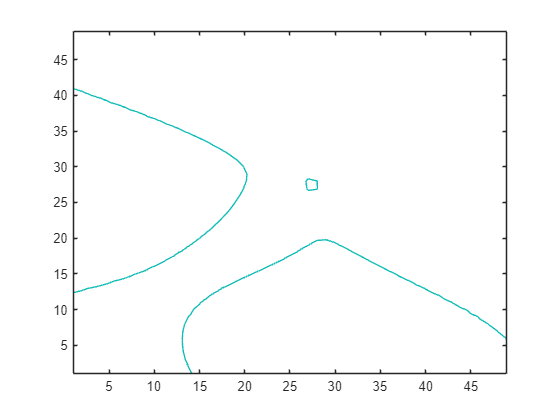

m =          0   14.1724   14.0000   13.7798   13.4335   13.2223   13.1111   13.0875   13.1570   13.3506   13.7557   14.0000   14.3067   15.0000   15.1255   16.0000   16.1594   17.0000   17.4525   18.0000   19.0000   19.0686   20.0000   20.7749   21.0000   22.0000   22.5146   23.0000   24.0000   24.1647   25.0000   25.6533   26.0000   26.9922   27.0000   28.0000   29.0000   30.0000   30.4966   31.0000   32.0000   32.0432   33.0000   33.5557   34.0000   35.0000   35.0668   36.0000   36.6827   37.0000
   70.0000    1.0000    1.4464    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000    9.2944   10.0000   10.7733   11.0000   11.7953   12.0000   12.5967   13.0000   13.3026   13.9458   14.0000   14.5257   15.0000   15.1130   15.6869   16.0000   16.2875   16.9013   17.0000   17.5861   18.0000   18.3078   19.0000   19.0094   19.6920   19.7855   19.3709   19.0000   18.7264   18.0306   18.0000   17.3585   17.0000   16.6820   16.0339   16.0000   15.3744   15.0000   14

m = contour(peaks, [0 0])